# 8. Classifying Sequence Data

## Investigate the Sequences

###     Load the musical instrument data

This contains 472 recordings of the Flute, Cello, and Piano, stored in cell arrays, along with their correct labels stored in categoricals. There is also a sampling rate of the recordings.

여기에는 categoricals에 저장된 올바른 레이블과 함께 셀 배열에 저장된 472개의 플루트, 첼로 및 피아노 녹음이 포함됩니다. 녹음의 샘플링 속도도 있습니다.

load classify3InstrumentsData.mat
%workspace가 보고 싶으면 whos
%cell형태가 아닌 자료형은 cell로 변형해서 사용. 혹은 table
%doc rand, randperm

Display the class distribution of the training data.

whos

  Name          Size               Bytes  Class          Attributes

  XTest        31x1               878168  cell                     
  XTrain      441x1             12481288  cell                     
  YTest        31x1                  375  categorical              
  YTrain      441x1                  785  categorical              
  ans           1x1                  345  categorical              
  fs            1x1                    8  double                   



XTrain

XTrain = 441×1 cell 배열
    {[0.0097 -8.3942e-05 -0.0276 -0.0264 -0.0088 0.0053 0.0176 0.0216 0.0233 -9.8232e-04 -0.0244 -0.0293 -0.0164 0.0066 0.0143 0.0199 0.0262 0.0066 -0.0193 -0.0311 -0.0243 0.0047 0.0162 0.0172 0.0277 0.0114 -0.0179 -0.0317 -0.0278 0.0013 0.0192 0.0159 0.0281 0.0172 -0.0182 -0.0324 -0.0322 -0.0032 0.0213 0.0148 0.0318 0.0252 -0.0167 -0.0342 -0.0414 -0.0105 0.0263 0.0187 0.0307 0.0278 -0.0144 -0.0341 -0.0424 -0.0180 0.0245 0.0212 0.0286 0.0370 -0.0049 -0.0338 -0.0460 -0.0318 0.0199 0.0252 0.0269 0.0442 0.0021 -0.0359 -0.0472 -0.0364 0.0170 0.0261 0.0272 0.0521 0.0080 -0.0378 -0.0534 -0.0467 0.0182 0.0300 0.0222 0.0545 0.0154 -0.0337 -0.0525 -0.0565 0.0115 0.0355 0.0207 0.0593 0.0261 -0.0392 -0.0549 -0.0617 0.0034 0.0436 0.0199 0.0580 0.0368 -0.0370 -0.0536 -0.0705 -0.0074 0.0498 0.0173 0.0587 0.0500 -0.0347 -0.0551 -0.0773 -0.0172 0.0546 0.0164 0.0572 0.0655 -0.0296 -0.0593 -0.0891 -0.0327 0.0650 0.0175 0.0507 0.0848 -0.0259 -0.0610 -0.0908 -0.0543 0.0674 0.0268 0.

XTrain{1}

ans =     0.0097   -0.0001   -0.0276   -0.0264   -0.0088    0.0053    0.0176    0.0216    0.0233   -0.0010   -0.0244   -0.0293   -0.0164    0.0066    0.0143    0.0199    0.0262    0.0066   -0.0193   -0.0311   -0.0243    0.0047    0.0162    0.0172    0.0277    0.0114   -0.0179   -0.0317   -0.0278    0.0013    0.0192    0.0159    0.0281    0.0172   -0.0182   -0.0324   -0.0322   -0.0032    0.0213    0.0148    0.0318    0.0252   -0.0167   -0.0342   -0.0414   -0.0105    0.0263    0.0187    0.0307    0.0278


YTrain(1)

ans = categorical
     Flute 


summary(YTrain)

     Flute      126 
     Cello      114 
     Piano      201 


x = XTrain{1}

x =     0.0097   -0.0001   -0.0276   -0.0264   -0.0088    0.0053    0.0176    0.0216    0.0233   -0.0010   -0.0244   -0.0293   -0.0164    0.0066    0.0143    0.0199    0.0262    0.0066   -0.0193   -0.0311   -0.0243    0.0047    0.0162    0.0172    0.0277    0.0114   -0.0179   -0.0317   -0.0278    0.0013    0.0192    0.0159    0.0281    0.0172   -0.0182   -0.0324   -0.0322   -0.0032    0.0213    0.0148    0.0318    0.0252   -0.0167   -0.0342   -0.0414   -0.0105    0.0263    0.0187    0.0307    0.0278


sound(x,fs)

###     Play some samples

These sequences can be played using the sampling rate `fs` and the function `sound`. Display the corresponding labels.

이러한 시퀀스는 샘플링 속도 fs와 기능 사운드를 사용하여 재생할 수 있습니다. 해당 라벨을 표시합니다.

idx = randperm(length(XTrain),3)

idx =    360   399    56


x = [XTrain{idx}]

x =     0.2257   -0.2355   -0.2517   -0.1736    0.2836    0.6168   -0.2805   -0.5697    0.2278    0.2351   -0.1254    0.0820   -0.1508   -0.0282    0.4029   -0.0020   -0.1365   -0.1889   -0.1461    0.1629    0.3638    0.1196   -0.5276   -0.0249    0.1336    0.1324    0.4161   -0.4812   -0.3955    0.1612    0.5409    0.3507   -0.7323   -0.2227    0.3487    0.4776    0.1816   -0.8268   -0.2763    0.4243    0.6376    0.1356   -0.8710   -0.3513    0.3313    0.8096    0.2592   -1.0291   -0.4506    0.4352


y = YTrain(idx)

y = 3×1 categorical 배열
     Piano 
     Piano 
     Flute 


sound(x,fs)

###     Plot the sound waves

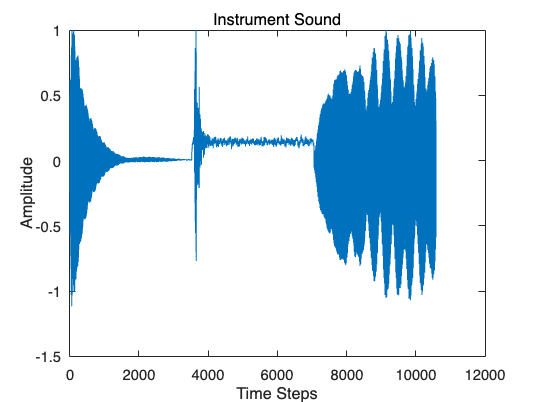

plot(x)
xlabel("Time Steps")
ylabel("Amplitude")
title("Instrument Sound")

## Create the Network

###     Assemble network layers

- Start with a sequence input layer with a single input node, since these sequences only have one features. 

- Follow with a BiLSTM layer with 100 nodes. Output only the last time step of each recording sample being classified. 

- End with a fully connected layer with one node for each instrument, a softmax layer, and a classificationLayer.

- 단일 입력 노드가 있는 시퀀스 입력 레이어로 시작하세요. 이러한 시퀀스에는 기능이 하나만 있기 때문입니다.

- 100개의 노드가 있는 BiLSTM 레이어를 따릅니다. 분류되는 각 녹음 샘플의 마지막 시간 간격만 출력합니다.

- 각 기기에 대해 하나의 노드, 소프트맥스 레이어 및 classificationLayer가 있는 완전히 연결된 레이어로 끝납니다.

layers = [
    sequenceInputLayer(1);
    bilstmLayer(100,"OutputMode","last");
    fullyConnectedLayer(3);
    softmaxLayer();
    classificationLayer()
    ]

layers =   다음 계층을 포함한 5×1 Layer 배열:

     1   ''   시퀀스 입력   시퀀스 입력 (차원 1개)
     2   ''   BiLSTM      BiLSTM (은닉 유닛 100개)
     3   ''   완전 연결     3 완전 연결 계층
     4   ''   소프트맥스    소프트맥스
     5   ''   분류 출력     crossentropyex

%신경만 네트워크 디자인 사용!

## Train the Network

###     Set training options

- Use the Adam optimizer

- Set the maximum number of epochs to 250

- The initial learning rate to 0.005

- The gradientThreshold to 1

- Plot the training progress

- Make it so the learning rate can drop for the first 60 epochs

options = trainingOptions("adam","MaxEpochs",250,...
    "Plots","training-progress","InitialLearnRate",0.005,...
    "GradientThreshold",1,"LearnRateSchedule","piecewise",...
    "LearnRateDropFactor",0.1,"LearnRateDropPeriod",60)

options =   TrainingOptionsADAM - 속성 있음:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.1000
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 250
                   MiniBatchSize: 128
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
  

###     Train the Network 

net = trainNetwork(XTrain, YTrain, layers, options)

## Load the trained Network

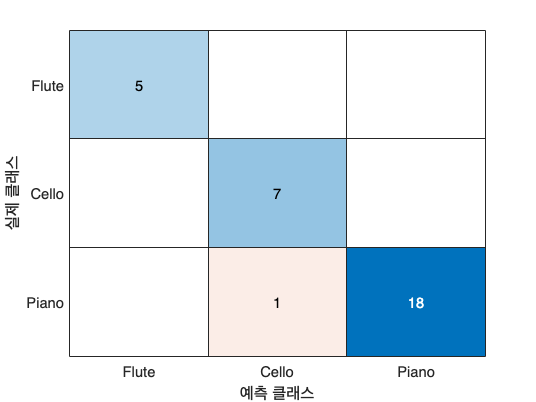

load net_LRDP200.mat % 'LearnRateDropPeriod' 200
% load net_LRDP50.mat % 'LearnRateDropPeriod' 50

## Classify and Evaluate the Network

testPred = classify(net, XTest);
confusionchart(YTest, testPred)